clear all
close all
load TR4_data.mat
syms x y z
S1=[link(2)*cos(pi/4) 0 link(2)*cos(pi/4)+link(3)*cos(pi/4)]

S1 =     0.0143         0    0.0355


S3=[80e-3 10e-3 20e-3];
eqn1=(x-S1(1))^2+(z-S1(3))^2-link(1)^2

$$eqn1 = {\left(z-\frac{5116641351640305}{144115188075855872}\right)}^{2}+{\left(x-\frac{4129183580331909}{288230376151711744}\right)}^{2}-\frac{1}{2500}$$

eqn3=(x-S3(1))^2+(y-S3(3))^2+(z-S3(2))^2-link(4)^2

$$eqn3 = {\left(x-\frac{2}{25}\right)}^{2}+{\left(y-\frac{1}{50}\right)}^{2}+{\left(z-\frac{1}{100}\right)}^{2}-\frac{1}{625}$$

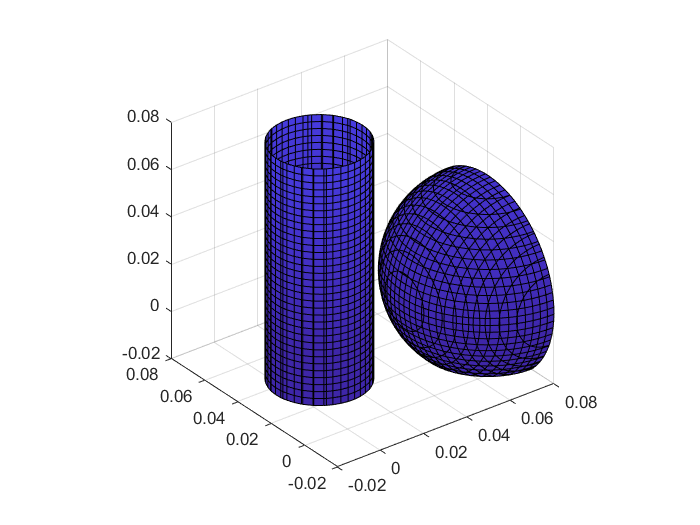

fimplicit3(eqn1)
hold on

fimplicit3(eqn3)
plot3(S1(1),S1(3),S1(2),'o')
plot3(S3(1),S3(3),S3(2),'o')
axis("equal")
xlim([-20e-3 80e-3])
ylim([-20e-3 80e-3])
zlim([-20e-3 80e-3])
hold off